# ANOVA Example

Andrew Brown

GEEN 3853

11/2/2020

## INTRODUCTION

Please read this article about the mental health of college students in the United States: 

[https://www.reuters.com/article/us-health-mental-undergrads/depression-anxiety-rising-among-u-s-college-students-idUSKCN1VJ25Z.](https://www.reuters.com/article/us-health-mental-undergrads/depression-anxiety-rising-among-u-s-college-students-idUSKCN1VJ25Z.)

The article states that “Suicidal thinking, severe depression and rates of self-injury among U.S. college students more than doubled over less than a decade...”. We will investigate this claim by comparing the depression symptoms in college-age people in 2007 to the depression symptoms of that same demographic in 2017.

### Research Questions

- To what extent did the frequency of depression symptoms over the two weeks prior to taking the PHQ-9 survey differ for college-age people (18-24 years old) in 2007-2008 and 2017-2018?

- How does the median level of depression-symptoms severity in 2007-2008 compare to that of the median level in 2017-2018?

 Use the suggested categories from Kroenke and Spitzer (2002) to answer this question.

## PREP WORKSPACE

clear all
close all
clc

# Import data from text file

Script for importing data from the following text file:

Auto-generated by MATLAB on 01-Nov-2020 20:53:10

## Setup the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 43);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["SEQN", "SDDSRVYR", "RIDSTATR", "RIDEXMON", "RIAGENDR", "RIDAGEYR", "RIDAGEMN", "RIDAGEEX", "RIDRETH1", "DMQMILIT", "DMDBORN2", "DMDCITZN", "DMDYRSUS", "DMDEDUC3", "DMDEDUC2", "DMDSCHOL", "DMDMARTL", "DMDHHSIZ", "DMDFMSIZ", "INDHHIN2", "INDFMIN2", "INDFMPIR", "RIDEXPRG", "DMDHRGND", "DMDHRAGE", "DMDHRBR2", "DMDHREDU", "DMDHRMAR", "DMDHSEDU", "SIALANG", "SIAPROXY", "SIAINTRP", "FIALANG", "FIAPROXY", "FIAINTRP", "MIALANG", "MIAPROXY", "MIAINTRP", "AIALANG", "WTINT2YR", "WTMEC2YR", "SDMVPSU", "SDMVSTRA"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
Demographics20072008 = readtable("C:\Users\andre\OneDrive\Documents\MATLAB\GEEN 3583\Demographics_2007_2008.csv", opts);
Demographics20072008(1:5,:)

ans = 5×43 table
    SEQN     SDDSRVYR    RIDSTATR    RIDEXMON    RIAGENDR    RIDAGEYR    RIDAGEMN    RIDAGEEX    RIDRETH1    DMQMILIT    DMDBORN2    DMDCITZN    DMDYRSUS    DMDEDUC3    DMDEDUC2    DMDSCHOL    DMDMARTL    DMDHHSIZ    DMDFMSIZ    INDHHIN2    INDFMIN2    INDFMPIR    RIDEXPRG    DMDHRGND    DMDHRAGE    DMDHRBR2    DMDHREDU    DMDHRMAR    DMDHSEDU    SIALANG    SIAPROXY    SIAINTRP    FIALANG    FIAPROXY  

## Clear temporary variables

clear opts

# Import data from text file

Script for importing data from the following text file:

Auto-generated by MATLAB on 01-Nov-2020 20:54:03

## Setup the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 11);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["SEQN", "DPQ010", "DPQ020", "DPQ030", "DPQ040", "DPQ050", "DPQ060", "DPQ070", "DPQ080", "DPQ090", "DPQ100"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
DepressionScreener20072008 = readtable("C:\Users\andre\OneDrive\Documents\MATLAB\GEEN 3583\DepressionScreener_2007_2008.csv", opts);
DepressionScreener20072008(1:5,:)

ans = 5×11 table
    SEQN     DPQ010    DPQ020    DPQ030    DPQ040    DPQ050    DPQ060    DPQ070    DPQ080    DPQ090    DPQ100
    _____    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______

    41475      1         0         1         1         1         1         0         0         0          0  
    41477      0         0         0         0         0         0         0         0         0        NaN  
    41479      0         0         0         0         0         0         0         0         0        NaN  
    41481      0         0         1         1         0  

## Clear temporary variables

clear opts

# Import data from text file

Script for importing data from the following text file:

Auto-generated by MATLAB on 01-Nov-2020 20:54:40

## Setup the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 46);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["SEQN", "SDDSRVYR", "RIDSTATR", "RIAGENDR", "RIDAGEYR", "RIDAGEMN", "RIDRETH1", "RIDRETH3", "RIDEXMON", "RIDEXAGM", "DMQMILIZ", "DMQADFC", "DMDBORN4", "DMDCITZN", "DMDYRSUS", "DMDEDUC3", "DMDEDUC2", "DMDMARTL", "RIDEXPRG", "SIALANG", "SIAPROXY", "SIAINTRP", "FIALANG", "FIAPROXY", "FIAINTRP", "MIALANG", "MIAPROXY", "MIAINTRP", "AIALANGA", "DMDHHSIZ", "DMDFMSIZ", "DMDHHSZA", "DMDHHSZB", "DMDHHSZE", "DMDHRGND", "DMDHRAGZ", "DMDHREDZ", "DMDHRMAZ", "DMDHSEDZ", "WTINT2YR", "WTMEC2YR", "SDMVPSU", "SDMVSTRA", "INDHHIN2", "INDFMIN2", "INDFMPIR"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
Demographics20172018 = readtable("C:\Users\andre\OneDrive\Documents\MATLAB\GEEN 3583\Demographics_2017_2018.csv", opts);
Demographics20172018(1:5,:)

ans = 5×46 table
    SEQN     SDDSRVYR    RIDSTATR    RIAGENDR    RIDAGEYR    RIDAGEMN    RIDRETH1    RIDRETH3    RIDEXMON    RIDEXAGM    DMQMILIZ    DMQADFC    DMDBORN4    DMDCITZN    DMDYRSUS    DMDEDUC3    DMDEDUC2    DMDMARTL    RIDEXPRG    SIALANG    SIAPROXY    SIAINTRP    FIALANG    FIAPROXY    FIAINTRP    MIALANG    MIAPROXY    MIAINTRP    AIALANGA    DMDHHSIZ    DMDFMSIZ    DMDHHSZA    DMDHHSZB    DMDHHSZE    

## Clear temporary variables

clear opts

# Import data from text file

Script for importing data from the following text file:

Auto-generated by MATLAB on 01-Nov-2020 20:55:00

## Setup the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 11);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["SEQN", "DPQ010", "DPQ020", "DPQ030", "DPQ040", "DPQ050", "DPQ060", "DPQ070", "DPQ080", "DPQ090", "DPQ100"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
DepressionScreener20172018 = readtable("C:\Users\andre\OneDrive\Documents\MATLAB\GEEN 3583\DepressionScreener_2017_2018.csv", opts);
DepressionScreener20172018(1:5,:)

ans = 5×11 table
    SEQN     DPQ010    DPQ020    DPQ030    DPQ040    DPQ050    DPQ060    DPQ070    DPQ080    DPQ090    DPQ100
    _____    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______

    93705      0         0         0         0         0         0         0         0         0         0   
    93706      0         0         0         0         0         0         0         0         0         0   
    93708      0         0         0         0         0         0         0         0         0         0   
    93709      0         0         0         0         0  

## Clear temporary variables

clear opts

## CLEAN AND SUBSET THE DATA

View the dataset and perform necessary cleanup.

%Turn needed data into arrays
rawEarlyDemo = table2array(Demographics20072008(:,["SEQN","RIDAGEYR"]));
rawLateDemo = table2array(Demographics20172018(3:9254,["SEQN","RIDAGEYR"]));
rawEarlyQuestions = table2array(DepressionScreener20072008(:,1:10));
rawLateQuestions = table2array(DepressionScreener20172018(1:5533,1:10));

%Find only people who answered all 9 questions
rawEarlyQuestions(:,10) = sum(rawEarlyQuestions,2);
rawLateQuestions(:,10) = sum(rawLateQuestions,2);

%Logical arrays with 1 for complete and 0 for incomplete
completeEarlyQuestions = ~isnan(rawEarlyQuestions(:,10)); 
completeLateQuestions = ~isnan(rawLateQuestions(:,10));

%Logical arrays with IDs for college age and 0 for not college age
collegeAgeEarlyIDs = zeros(752,1);
collegeAgeLateIDs = zeros(692,1);
countAgeEarly = 0;
countAgeLate = 0;

for i=1:10149
    if rawEarlyDemo(i,2) >= 18 && rawEarlyDemo(i,2) <= 24
        countAgeEarly = countAgeEarly + 1;
        collegeAgeEarlyIDs(countAgeEarly,1) = rawEarlyDemo(i,1);
    end
end

for i=1:9252
    if rawLateDemo(i,2) >= 18 && rawLateDemo(i,2) <= 24
        countAgeLate = countAgeLate + 1;
        collegeAgeLateIDs(countAgeLate,1) = rawLateDemo(i,1);
    end
end

%Get arrays with only the IDs of the completed questions

completeEarlyQuestionIDs = zeros(5447,1);
completeLateQuestionIDs = zeros(5533,1);

countCompleteEarly = 0;
countCompleteLate = 0;

for i=1:5995
    if completeEarlyQuestions(i,1) == 1
       countCompleteEarly = countCompleteEarly + 1;
       completeEarlyQuestionIDs(countCompleteEarly,1) = rawEarlyQuestions(i,1);
    end
end

for i=1:5533
    if completeLateQuestions(i,1) == 1
       countCompleteLate = countCompleteLate + 1;
       completeLateQuestionIDs(countCompleteLate,1) = rawLateQuestions(i,1);
    end
end

%Get arrays with only IDs of completed questions from college age people
idDataEarly = zeros(672,1);
idDataLate = zeros(650,1);

countEarly = 0;
countLate = 0;

for i=1:5447
    j=1;
    while completeEarlyQuestionIDs(i,1) ~= collegeAgeEarlyIDs(j,1)
        j = j + 1;
        if j == 752
            break;
        end
    end
    if completeEarlyQuestionIDs(i,1) == collegeAgeEarlyIDs(j,1)
        countEarly = countEarly + 1;
        idDataEarly(countEarly,1) = collegeAgeEarlyIDs(j,1);
    end
end

for i=1:5533
    j=1;
    while completeLateQuestionIDs(i,1) ~= collegeAgeLateIDs(j,1)
        j = j + 1;
        if j == 692
            break;
        end
    end
    if completeLateQuestionIDs(i,1) == collegeAgeLateIDs(j,1)
        countLate = countLate + 1;
        idDataLate(countLate,1) = collegeAgeLateIDs(j,1);
    end
end

%Get arrays with question answers for college age completed questions

completeDataEarly = zeros(672,10);
completeDataLate = zeros(650,10);

finalCounterEarly = 0;
finalCounterLate = 0;

for i=1:672
    j=1;
    while idDataEarly(i,1) ~= rawEarlyQuestions(j,1)
        j = j + 1;
    end
    if idDataEarly(i,1) == rawEarlyQuestions(j,1)
        finalCounterEarly = finalCounterEarly + 1;
        for k=1:9
            completeDataEarly(finalCounterEarly,k) = rawEarlyQuestions(j,k);
        end
    end
end

for i=1:650
    j=1;
    while idDataLate(i,1) ~= rawLateQuestions(j,1)
        j = j + 1;
    end
    if idDataLate(i,1) == rawLateQuestions(j,1)
        finalCounterLate = finalCounterLate + 1;
        for k=1:9
            completeDataLate(finalCounterLate,k) = rawLateQuestions(j,k);
        end
    end
end

%Get complete sum data.
completeSumDataEarly = zeros(672,1);
completeSumDataLate = zeros(650,1);

for i=1:672
    completeSumDataEarly(i,1) = sum(completeDataEarly(i,2:10));
end

for i=1:650
    completeSumDataLate(i,1) = sum(completeDataLate(i,2:10));
end


## DESCRIPTIVE STATISTICS - VISUAL

### Histograms

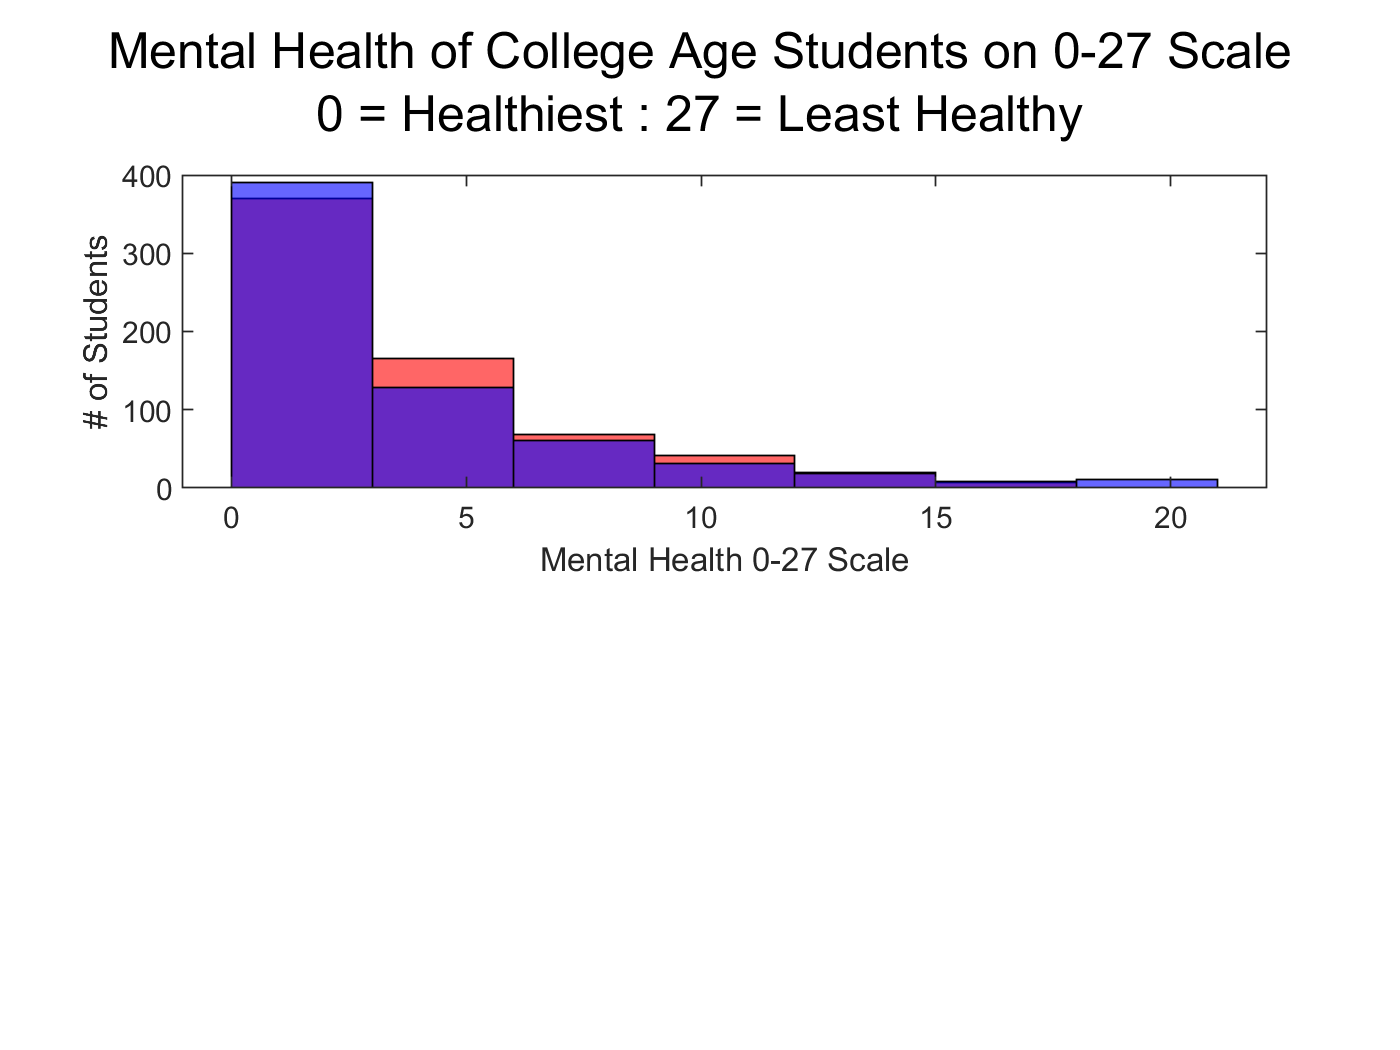

%Obtain the histogram plot of the dataset
figure
subplot(2,1,1)
histogram(completeSumDataEarly,'Binwidth',3,'FaceColor','red')
hold on
histogram(completeSumDataLate,'Binwidth',3,'FaceColor','blue')
hold off
xlabel('Mental Health 0-27 Scale')
ylabel('# of Students')

sgtitle("Mental Health of College Age Students on 0-27 Scale"+newline+"0 = Healthiest : 27 = Least Healthy")

## TEST OF DIFFERENCE

For a 4 sample, independent, and non-parametric population, we have NO assumptions.

We only know the following:

- Random, Representative samples.

- All samples come from populations having the same continuous distribution.

- All observations are mutually independent.

Method: Kruskal-Wallis Rank ANOVA

Step 1 : (Note that a non-directional test is assumed.)

H0 : All means are equal 

H1: All means are not equal (at least two means are statistically different)

Step 2: Alpha level; i.e., significance level, or how much Type I error you are willing to make is 1%.

Step 3 : We will use the H statistic.

Step 4 : We will use the RSD for F with 3 and 140 degrees of freedom. ***NEED HELP ON THIS

Step 5 : State the Critical Value for Rejecting the Null Hypothesis

    We will reject the null if H < chi squared distribution or if the p-value < alpha

Step 6: Calculations

[p_anova,tbl_anova,stats_anova] = kruskalwallis(dataLong,numsLong)

Unrecognized function or variable 'dataLong'.

c = multcompare(stats_anova)

### Decision

Step 7a) Decision : **Reject H0**

7b) p < .001 (p less than alpha)

7c) We have sufficient statistical evidence to infer that the means of one or more of the populations from which these samples were drawn are unequal. (If equal: The difference between mu_1 and mu_2 is due to sampling error, and sampling error alone.)

7d) Appropriate Point Estimates (Salary in USD)

    *M_Men = $194,910.00   |  M_Women = $130,880.00  |  M_AssistantProfMen = $197,840.00* *|  M_AssistantProfWomen = $119,800.00*

*Convert 7's and 9's to NaNs *

For 2 groups that are independent and non-parametric, we will utilize the Mann-Whitney-U Test for the Post-Hoc analysis along with the Bonferoni Method to control our Type I error.

Use p-value from MW-U test and compare to bonferroni alpha value.

Effect Size is epsilon squared and it is the percent variance explained by the differences in our locations of the groups.

        - Assumes same shape and spread.